# Estructuras de datos: Tablas

Hasta este punto se hemos trabajado con matrices (las cuales tienen la característica de tener el mismo tipo de dato). Sin embargo, si toda esta información está relacionada y cada fila/columna representa algo, entonces lo ideal sería unir toda esta información para su posterior análisis. 

**Figura 1.** Información relacionada entre sí, pero guardada en vectores independientes.

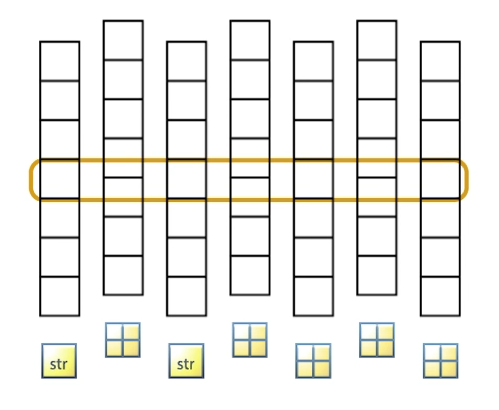

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

Una buena alternativa sería unir toda la información en una matriz, pero si la información concatenada no tiene el mismo tipo de dato, entonces obtendríamos un error.

**Figura 2.** Información relacionada entre sí y "guardada" en una matriz.

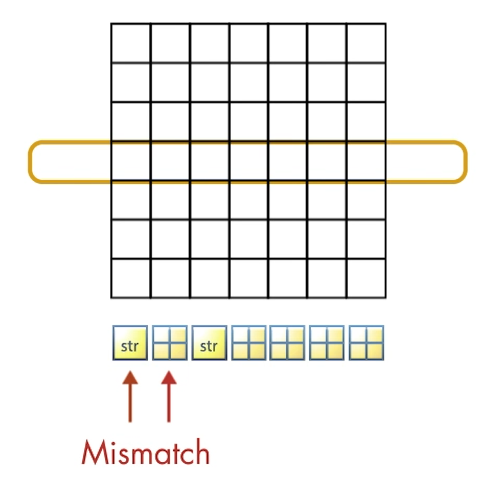

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

Por lo tanto, lo ideal sería utilizar una estructura que no tenga estas limitaciones, la cual nos permita unir toda la información a pesar de que hayan columnas de diferente tipo de dato. Esta estructura se conoce como **tabla**.

Las tablas son un tipo de dato adecuado para datos tabulares que a menudo se almacenan como columnas en un archivo de texto o en una hoja de cálculo. Las tablas constan de **observaciones** (filas) y **variables** (columnas).

**Figura 3.** Ilustración de una tabla en MATLAB.

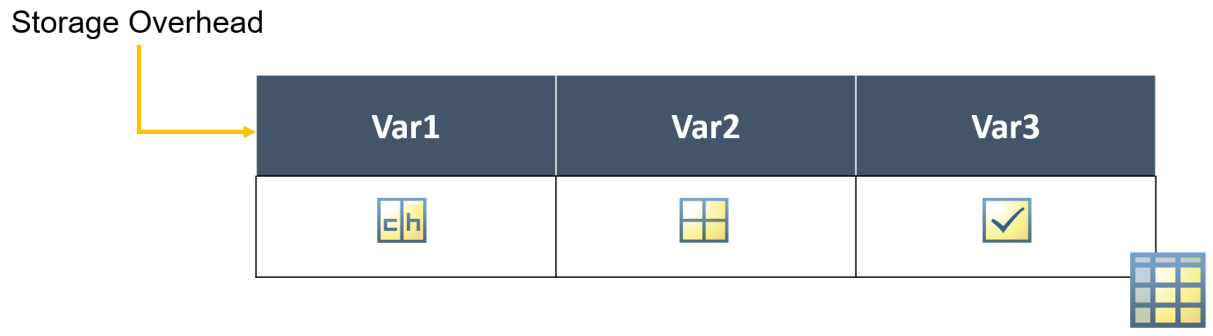

*Tomado de MATLAB Programming Techniques Quick Reference.*

**Cada variable en una tabla puede tener un tipo de dato diferente del resto de variables. Sin embargo, la única restricción es que cada variable debe tener el mismo número de observaciones.**

Además, no está restringido que una variable sea de una sola columna. Es decir, una variable puede contener varias columnas, siempre y cuando todas estas tengan el mismo número de filas.

Cabe destacar que las tablas (también llamadas *arreglos tabla*) son **contenedores de datos**. Esto es relevante dado que cuando se indexa una tabla es posible extraer una *subtabla* (conjunto reducido de datos de la tabla que sigue siendo una tabla) o es posible extraer directamente el contenido de la tabla.

**Figura 4.** Visualización de un contenedor y el contenido.

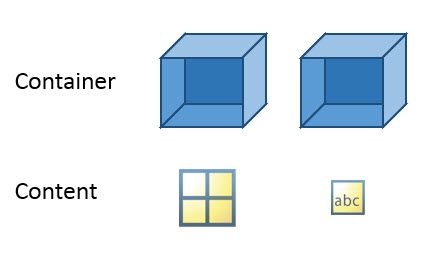

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

## Crear una tabla

Las tablas dentro de MATLAB son de clase `table` y se pueden crear de distintas formas, aunque la más usual es ingresando las variables en la función `table`.

### Función `table`

La función `table` permite crear una tabla de distintas formas, pero la más común es ingresando las variables.

**Todas las variables deben tener el mismo número de filas.**

% Ingrese su código aquí :)

#### Observación

La visualización de una tabla dentro del live script es muy útil. No obstante, en bastante documentación también se encontrará la visualización de la ventana de comandos (la cual se replica utilizando la función `disp`), por ende se recomienda intentar familiarizarse con ambas formas, no sólo con una.

% Ingrese su código aquí :)

### Función `array2table`

La función `array2table` permite convertir una matriz en una tabla.

% Ingrese su código aquí :)

## Modificar las propiedades de una tabla

Para modificar las propiedades de una tabla se utiliza la **notación punto**, por lo que conviene explicar esta notación.

La notación punto hace referencia a las variables de la tabla por nombre, `T.varname`, donde `T` es la tabla y `varname` es el nombre de la variable a la cual se accede a través de esta notación (utilizando un punto).

La notación punto se puede utilizar para indexar elementos, añadir o quitar elementos, etc.; pero también se la puede utilizar para acceder a las propiedades de la tabla: `Properties`.

% Ingrese su código aquí :)

Podemos modificar cualquiera de las propiedades de una tabla accediendo a éstas mediante la notación punto de nuevo. Las propiedades más usuales para modificar son el nombre de las variables, `VariableNames`, y el nombre de las observaciones, `RowNames`.

% Ingrese su código aquí :)

## Indexación de tablas

Para detallar la indexación de tablas primero se creará una con el MAT-file "patients.mat" que se encuentra dentro de MATLAB como base de datos de ejemplo.

% Ingrese su código aquí :)

### Indexación por posición

La indexación por posición estudiada en el tema de matrices también es válida para trabajar con tablas utilizando el mismo concepto.

El resultado de la indexación también es una tabla.

**Figura 5.** Diferencia entre indexación con paréntesis e indexación con llaves (*curly braces*).

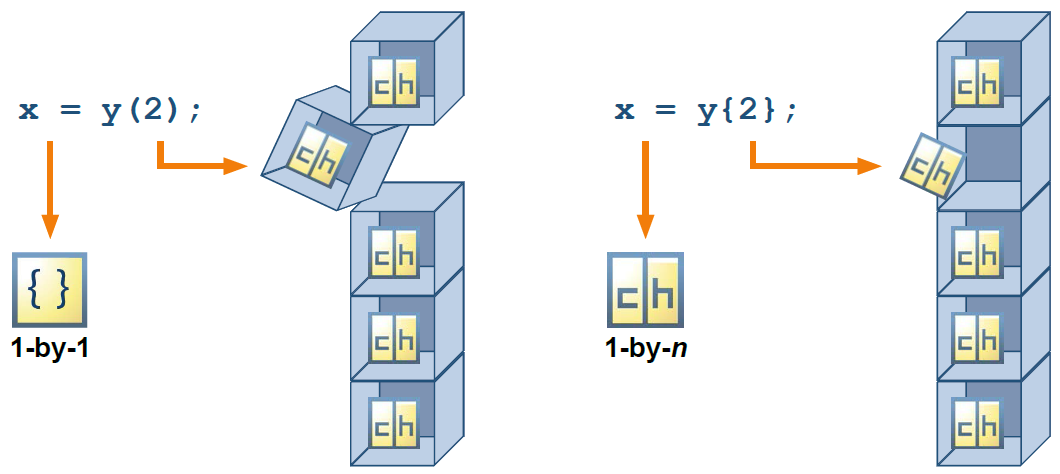

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

**Aclaración:** Figura utilizada originalmente para explicar la diferencia entre paréntesis `()` y llaves `{}` de esta indexación en arreglos celda, aunque el funcionamiento es el mismo para arreglos tabla.

% Ingrese su código aquí :)

### Indexación utilizando los nombres de las variables

Cuando se indexa a través de la notación punto, hay dos formas de especificar una variable.

- **Por nombre, sin comillas.** Por ejemplo, `T.Nombres`.

- **Por una expresión, donde la expresión está encerrada entre paréntesis después del punto.** Por ejemplo, `T.("Fecha de inicio")`.

Se utiliza la primera sintaxis cuando el nombre de una variable tabular también es un identificador válido de MATLAB. Es decir, cuando el nombre de la variable sigue las reglas para nombrar variables dentro de MATLAB (letras, números y guión bajo).

**Figura 6.** Indexación de una tabla.

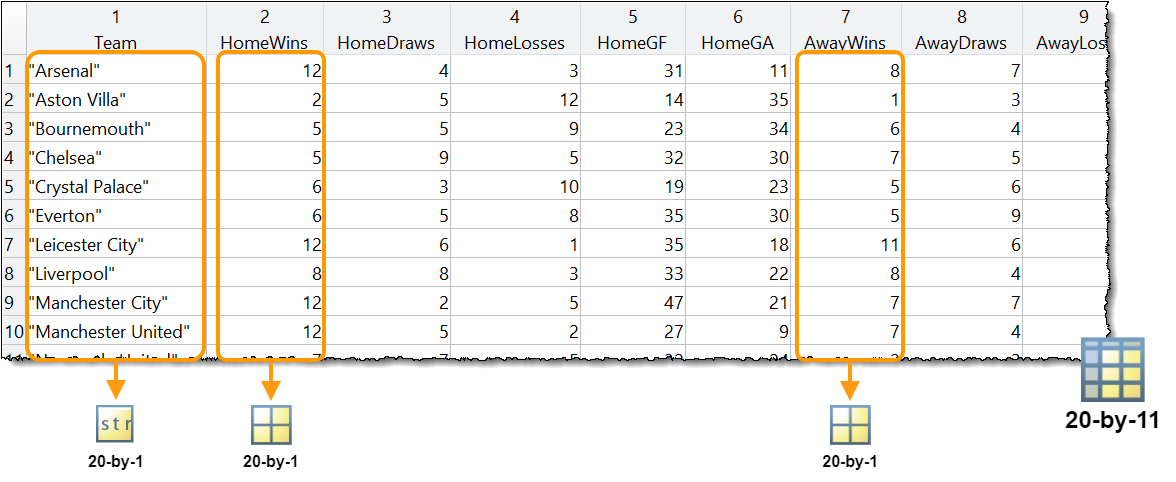

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

Por otra parte, se utiliza la segunda sintaxis cuando se especifica:

- Un número que indica la posición de la variable en la tabla.

- Un nombre de variable que no es un identificador válido de MATLAB.

- Cuando se agregan variables con identificadores no válidos de MATLAB.

El resultado de la indexación utilizando la notación punto tiene el **mismo tipo de dato** que la variable indexada. Esto se debe a que esta indexación extrae el contenido de la variable.

% Ingrese su código aquí :)

### Agregar/quitar variables a una tabla

Existen diferentes formas para agregar una variable a una tabla, pero la más común es utilizar la notación punto.

% Ingrese su código aquí :)

Por otra parte, para quitar una variable de la tabla también se utiliza la notación punto, indexando la variable que se desea eliminar y asignándole la matriz vacía.

% Ingrese su código aquí :)

## Funciones para trabajar con tablas

Existen diversas funciones que están diseñadas para trabajar con tablas, así que a continuación se detallan las más usuales.

### Funciones `width` y `height`

Para conocer el número de variables (o columnas) de una tabla se utiliza la función `width`, mientras que para conocer el número de observaciones (o filas) se utiliza la función `height`.

Es decir, en lugar de utilizar la función `size` o `length` para determinar las dimensiones de una tabla, se utilizan las funciones previamente mencionadas.

% Ingrese su código aquí :)

### Funciones `head` y `tail`

La función `head` permite visualizar las *k-ésimas* primeras observaciones. Por defecto $k$ es igual a 8.

% Ingrese su código aquí :)

Evidentemente la función `head` mostrará las primeras 8 observaciones siempre que la tabla las tenga, caso contrario mostrará todas las que haya.

Por otra parte, la función `tail` permite visualizar las últimas *k-ésimas* observaciones. Por defecto $k$ es igual a 8.

% Ingrese su código aquí :)

Al igual que la función `head`, la función `tail` mostrará las últimas 8 observaciones siempre que la tabla las tenga, caso contrario mostrará todas las que haya.

### Función `movevars`

La función `movevars` permite mover las variables de una tabla. A continuación se muestra una imagen de cómo se realiza esto.

**Figura 7.** Visualización de cómo trabaja la función `movevars`.

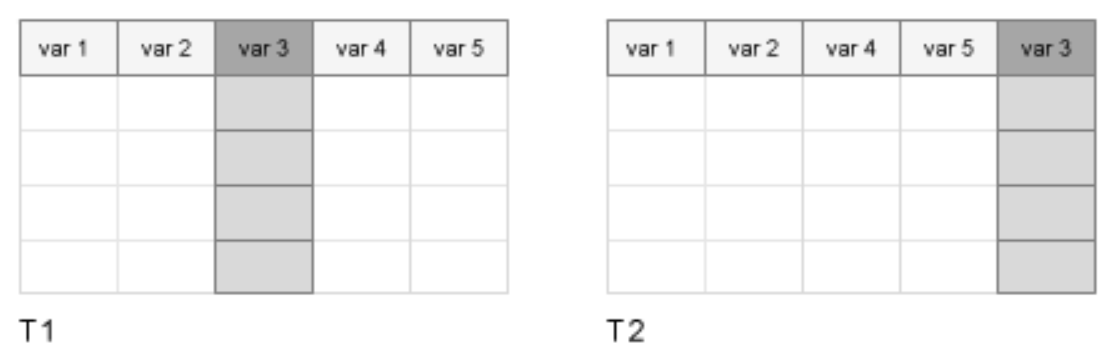

*Tomado de *[*MathWorks: *`movevars`](https://www.mathworks.com/help/matlab/ref/table.movevars.html)*.*

`A continuación se muestra un ejemplo de esto.`

% Ingrese su código aquí :)

## Realizar cálculos con tablas

Hasta este momento se ha realizado diferentes ejercicios y ejemplos utilizando funciones para clases numéricas (enteros y decimales), arreglos cadena y arreglos caracter, y para valores lógicos.

Ahora bien, en una tabla es posible reasignar a una variable la misma variable modificada (aplicando algún cálculo, función, etc.), o simplemente creando una variable a partir de otras.

% Ingrese su código aquí :)

## Material adicional

- [Tablas](https://www.mathworks.com/help/matlab/tables.html)

- [Ventajas de usar tablas](https://www.mathworks.com/help/matlab/matlab_prog/advantages-of-using-tables.html)

- [Crear tablas y asignarles información](https://www.mathworks.com/help/matlab/matlab_prog/create-a-table.html)

- [Acceder a información de una tabla](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

- [Agregar, eliminar y reorganizar variables de tabla](https://www.mathworks.com/help/matlab/matlab_prog/add-and-delete-table-variables.html)

- [Cálculos en tablas](https://www.mathworks.com/help/matlab/matlab_prog/calculations-on-tables.html)

- [Modificar unidades, descripciones y nombres de variables de tabla](https://www.mathworks.com/help/matlab/matlab_prog/modify-units-descriptions-and-table-variable-names.html)

- [Conjuntos de datos de muestra](https://www.mathworks.com/help/stats/sample-data-sets.html)